## Example 3.45 [2]

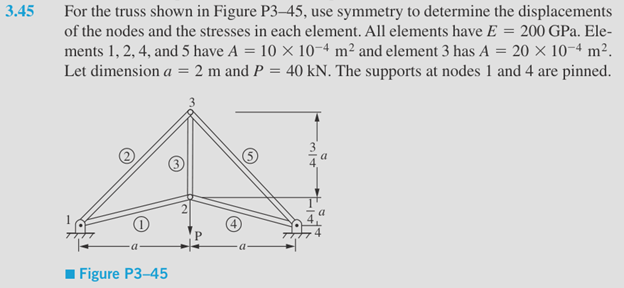

% Geometric data
a = 2; %m
connect_vec = [1 2; 1 3; 2 3; 2 4; 3 4];
crd = [0 0; a a/4; a a; 2*a 0];

len = zeros(5,1);
len([1,4]) = norm(crd(2,:) - crd(1,:));
len(3) = 3*a/4;
len([2,5]) = norm(crd(3,:) - crd(1,:));

E = 200e9*ones(1,5); % Pa
A = zeros(5,1);
A([1,2,4,5]) = 10e-4; %m2
A(3) = 20e-4

A =     0.0010
    0.0010
    0.0020
    0.0010
    0.0010


stf = BarElStiffness(E,A,len)        % Stiffnes for each element

stf = 1.0e+08 *

    0.9701
    0.7071
    2.6667
    0.9701
    0.7071



a_vec = [0 0 1 1 1 1 0 0];
F = zeros(size(a_vec,2),1);
F([3,4]) = [0;-40e3]

F =            0
           0
           0
      -40000
           0
           0
           0
           0



U = zeros(2*4,1);
Fa = F(a_vec ~= 0);           % Active forces
Uc = U(a_vec == 0);           % Constrained displacements

KG = KAssembly(connect_vec, stf, crd, "2d")     % Assemble the global Stiffness Matrix

KG = 1.0e+08 *

    1.2666    0.5818   -0.9131   -0.2283   -0.3536   -0.3536         0         0
    0.5818    0.4106   -0.2283   -0.0571   -0.3536   -0.3536         0         0
   -0.9131   -0.2283    1.8262         0         0         0   -0.9131    0.2283
   -0.2283   -0.0571         0    2.7808         0   -2.6667    0.2283   -0.0571
   -0.3536   -0.3536         0         0    0.7071         0   -0.3536    0.3536
   -0.3536   -0.3536         0   -2.6667         0    3.3738    0.3536   -0.3536
         0         0   -0.9131    0.2283   -0.3536    0.3536    1.2666   -0.5818
         0         0    0.2283   -0.0571    0.3536   -0.3536   -0.5818    0.4106


M = partitionMatrix(KG, a_vec);                 % Partitioning the matrix 

[Ua, Fc] = UFSolver(M, Uc, Fa);     % Unkonwn displacements and reaction forces

F(a_vec == 0) = Fc

F = 1.0e+04 *

    3.0175
    2.0000
         0
   -4.0000
         0
         0
   -3.0175
    2.0000


U(a_vec ~= 0) = Ua               % Assign unknown displacements to the corresponding indices

U = 1.0e-03 *

         0
         0
         0
   -0.5943
         0
   -0.4698
         0
         0



[STRAIN, STRESS] = postProcess(connect_vec,crd,U,E)     

STRAIN = 1.0e-03 *

   -0.0699
   -0.1174
    0.0830
   -0.0699
   -0.1174


STRESS = 1.0e+07 *

   -1.3984
   -2.3488
    1.6608
   -1.3984
   -2.3488


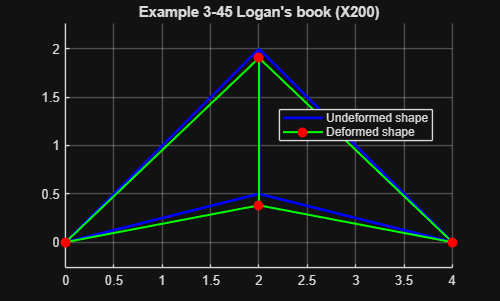

plotTruss(connect_vec,crd,U,200, "Example 3-45 [2]")        


% Check for equilibrium
assert(sum(F) < 1e-6)